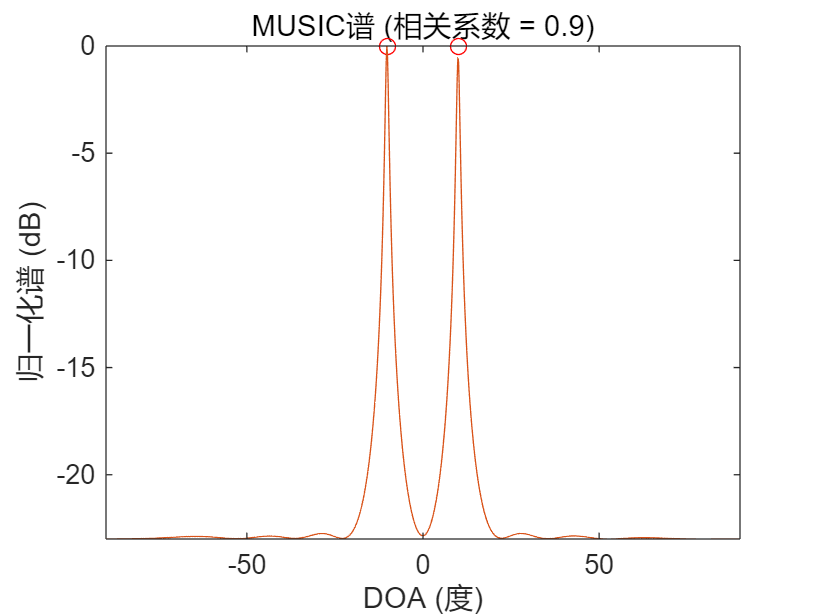

% 实验：MUSIC和ESPRIT对信号源相关性的敏感性
clear; clc; close all;

% 参数设置
N = 10; % 传感器数量
M = 2; % 信号源数量
doas_deg = [-10, 10]; % 真实DOA（度）
doas_rad = deg2rad(doas_deg); % 转换为弧度
wavelength = 1; % 波长（归一化）
d = 0.5; % 传感器间距（半波长）
snr_db = 10; % 信噪比（dB）
noise_var = 10^(-snr_db/10); % 噪声功率
snapshots = 100; % 快照数
corr_coeffs = [0, 0.5, 0.9]; % 相关系数
n_trials = 100; % 蒙特卡洛试验次数
grid_size = 1000; % MUSIC网格点数

% 阵列设置
design = ula_1d(N, d, 'ULA_10');

% 仿真循环
mse_music = zeros(length(corr_coeffs), 1);
mse_esprit = zeros(length(corr_coeffs), 1);
crb_vals = zeros(length(corr_coeffs), 1); % 平均CRB
music_cov_vals = zeros(length(corr_coeffs), 1); % MUSIC理论协方差
for c = 1:length(corr_coeffs)
    rho = corr_coeffs(c);
    % 源协方差矩阵（单位功率，相关系数rho）
    scov = [1, rho; rho, 1];
    
    mse_music_trial = zeros(n_trials, 1);
    mse_esprit_trial = zeros(n_trials, 1);
    
    for t = 1:n_trials
        % 生成快照
        [X, R] = snapshot_gen_sto(design, doas_rad, wavelength, snapshots, noise_var, scov);
        
        % MUSIC
        sp_music = music_1d(R, M, design, wavelength, grid_size, 'Unit', 'degree', 'RefineEstimates', true);
        doa_music = sp_music.x_est;
        mse_music_trial(t) = mean((sort(doa_music) - doas_deg).^2); % 排序确保对应
        
        % ESPRIT
        k = 2 * pi * d / wavelength; % 归一化常数
        sp_esprit = esprit_1d(R, M, k, 'Unit', 'degree', 'Formulation', 'TLS');
        doa_esprit = sp_esprit.x_est;
        mse_esprit_trial(t) = mean((sort(doa_esprit)' - doas_deg).^2); % 排序确保对应
    end
    
    mse_music(c) = mean(mse_music_trial);
    mse_esprit(c) = mean(mse_esprit_trial);
    
    % 计算CRB
    CRB = crb_general_sto_1d(design, wavelength, doas_rad, scov, noise_var, snapshots);
    crb_vals(c) = mean(diag(CRB)) * (180/pi)^2; % 转换为度^2
    
    % 计算MUSIC理论协方差
    C_music = ecov_music_1d(design, wavelength, doas_rad, scov, noise_var, snapshots);
    music_cov_vals(c) = mean(diag(C_music)) * (180/pi)^2; % 转换为度^2
end

% 可视化MUSIC谱（以最后一个相关系数为例）
[X, R] = snapshot_gen_sto(design, doas_rad, wavelength, snapshots, noise_var, scov);
sp_music = music_1d(R, M, design, wavelength, grid_size, 'Unit', 'degree', 'RefineEstimates', true);
sp_music.true_positions = doas_deg; % 添加真实DOA用于绘图
figure;
plot_sp(sp_music, 'PlotType', 'cartesian', 'UseDBScale', true, ...
        'Title', sprintf('MUSIC谱 (相关系数 = %.1f)', corr_coeffs(end)), ...
        'XLabel', 'DOA (度)', 'YLabel', '归一化谱 (dB)');

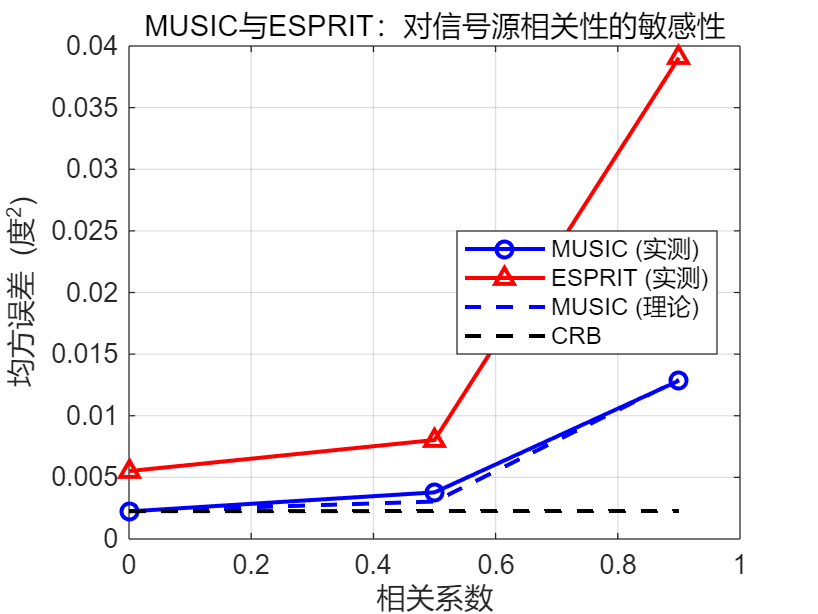


% 绘制MSE曲线
figure;
plot(corr_coeffs, mse_music, 'b-o', 'LineWidth', 1.5, 'DisplayName', 'MUSIC (实测)');
hold on;
plot(corr_coeffs, mse_esprit, 'r-^', 'LineWidth', 1.5, 'DisplayName', 'ESPRIT (实测)');
plot(corr_coeffs, music_cov_vals, 'b--', 'LineWidth', 1.5, 'DisplayName', 'MUSIC (理论)');
plot(corr_coeffs, crb_vals, 'k--', 'LineWidth', 1.5, 'DisplayName', 'CRB');
hold off;
xlabel('相关系数');
ylabel('均方误差 (度^2)');
title('MUSIC与ESPRIT：对信号源相关性的敏感性');
legend('Location', 'best');
grid on;